# Chap 1. 

## Matlab 기초

1. 변수

% 행렬
a = 1;                       % Scalar
x1 = [0, 2, 4, 8, 16];       % 행 벡터
x2 = [0, 2, 4, 8, 16]';      % 열 벡터
X3 = [1 2 3 4; 5 6 7 8];     % 행렬
X3 = [1 2 3 4; 5 6 7 8];     % transposition

2. 생성

% one matrix
a = ones(5,2);
% zero matrix
b = zeros(4,3);
% identity
c = eye(4);


3. 연산

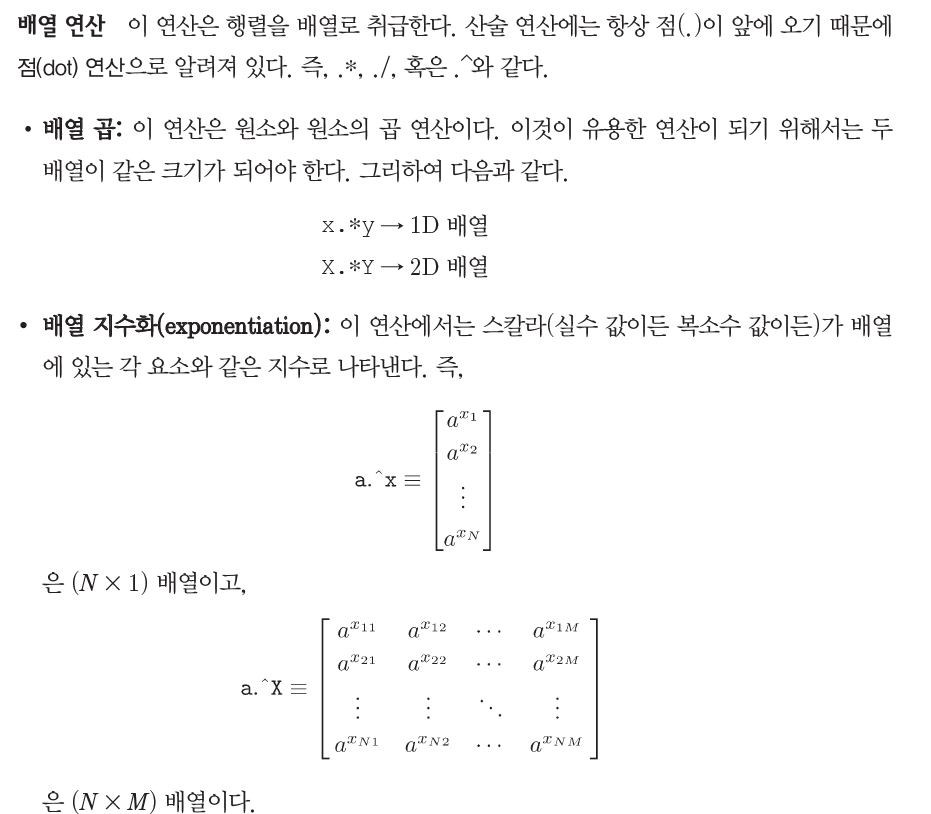

x = [2 4 6 8];
y = [1 2 3 4];
x*y'

ans = 60

x.*y

ans =      2     8    18    32


x.^y

4. 인덱싱

% 결과를 확인하세요.
x = [1:2:10; 1:0.5:3];
x_1 = x(:);
x_2 = x(:,2);
x_3 = x(1,:);
x
x_1
x_2
x_3

### 예제 1.1 다음 정현 함수의 합을 고려해보자

t = 0:0.01:1;
xt = zeros(1, length(t));
for k=1:3
    xt = xt + (1/k)*sin(2*pi*k*t);
end

5. function

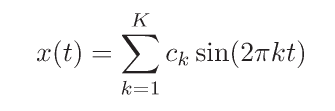

t = 0:0.01:1;
k = 1:2:5;
ck = 1./k;
xt = sinsum(t,ck);
xt

6. Plot

t = 0:0.01:1;
x = sin(2*pi*t);

figure(1)
plot(t,x,'b');
xlabel('t in sec');
ylabel('x(t)');
title('Plot of sin function');
figure(2)
n = 0:1:40;
x = sin(0.1*pi*n);
Hs = stem(n,x,'b','filled');
set(Hs, 'markersize', 4);
xlabel('n'); ylabel('x(n)');
title('Stem Plot of sin(0.2 pi n)');

Subplot

% Subplot
subplot(2,1,1);
t = 0:0.01:1;
x = sin(2*pi*t);
plot(t,x,'b');

n = 0:1:40;
x = sin(0.1*pi*n);
subplot(2,1,2);
Hs = stem(n,x,'b','filled');

### 1.3 디지털 신호 처리의 응용

악음 처리 (Musical Sound)

load handel;
sound(y,Fs);
pause(10);
alpha = 0.9;
D = 4196;
b = [1, zeros(1,D), alpha]
x = filter(b,1,y);
sound(x,Fs)

### 예제 1.2 다음 정현파의 파형을 그려라

- x(t) = Acos(2*pi*f*t + phi)

- 샘플링 주기가 다른 이산 정현파 : f = 1, phi = 0, A = 1, T = 0.05, 0.1, 0.2

function xt = sinsum(t,ck)
    K = length(ck);
    k = 1:K;
    ck = ck(:)';
    t = t(:)';
    xt = ck*sin(2*pi*k'*t);
end